Peter Corke Simulation of Right Leg Exoskeleton

startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2019 http://www.petercorke.com
Neither Robotics Toolbox or MachineVision Toolbox found in C:\Users\allen\AppData\Roaming\MathWorks\MATLAB Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\lib
     ** this is at least 2 years old, you may have issues
** Toolbox function rotx is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\phased\phased\rotx.m
** Toolbox function roty is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\phased\phased\roty.m
** Toolbox function rotz is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\phased\phased\rotz.m
** Toolbox function angdiff is shadowed by C:\Program Files\MATLAB\R2023b\toolbox\shared\robotics\robotutils\angdiff.m
Some Toolbox files are "shadowed" and will cause problems with the use of this toolbox
Use path tool to move this Toolbox to the top of the path


disp("Left Leg")

Left Leg


syms a1 a2 a3 a4 a5

a1 = 0.100  % 100mm = 0.100 m

a1 = 0.1000

a2 = 0.367  % 367mm = 0.367 m

a2 = 0.3670

a3 = 0.3436 % 343.6mm = 0.3436m

a3 = 0.3436

a4 = 0.06553 % 65.53mm = 0.06553 m

a4 = 0.0655

a5 = 0.0865 % 86.5mm = 0.0865m

a5 = 0.0865


H_L0L1 = Revolute('offset', pi/2, 'alpha', 3*pi/2, 'd', a1, 'qlim', [0 0])

 
H_L0L1 = 
Revolute(std): theta=q, d=0.1, a=0, alpha=4.71239, offset=1.5708


H_L1L2 = Revolute('offset', pi/2, 'a', a2, 'qlim', [-30*pi/180 140*pi/180])

 
H_L1L2 = 
Revolute(std): theta=q, d=0, a=0.367, alpha=0, offset=1.5708


H_L2L3 = Revolute('a', a3, 'qlim', [-140*pi/180 0])

 
H_L2L3 = 
Revolute(std): theta=q, d=0, a=0.3436, alpha=0, offset=0


H_L3L4 = Revolute('a', a4, 'd', -a5, 'qlim', [-50*pi/180 -30*pi/180])

 
H_L3L4 = 
Revolute(std): theta=q, d=-0.0865, a=0.06553, alpha=0, offset=0



LeftLEG = SerialLink([H_L0L1 H_L1L2 H_L2L3 H_L3L4])

 
LeftLEG = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        0.1|          0|    4.71239|     1.5708|
|  2|         q2|          0|      0.367|          0|     1.5708|
|  3|         q3|          0|     0.3436|          0|          0|
|  4|         q4|    -0.0865|    0.06553|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


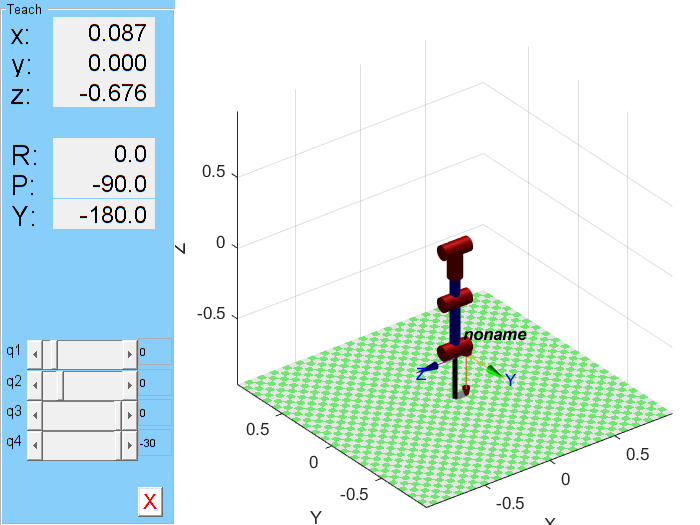


LeftLEG.teach()